# JoyStick Demo - Gator Summer 2022

### REV A

Joystick Demo to drive the Gator via a usb connected joystick to the main system

%%% Path Declaration
addpath(...
    "ACT\",...
    "GPSCOORDS\",...
    "SENSE\",...
    "SETUP\",...
    "SHUTDOWN\",...
    "THINK\",...
    "TESTING\","RTK_GPS\")
disp("FOLDER PATHS ADDED")

FOLDER PATHS ADDED


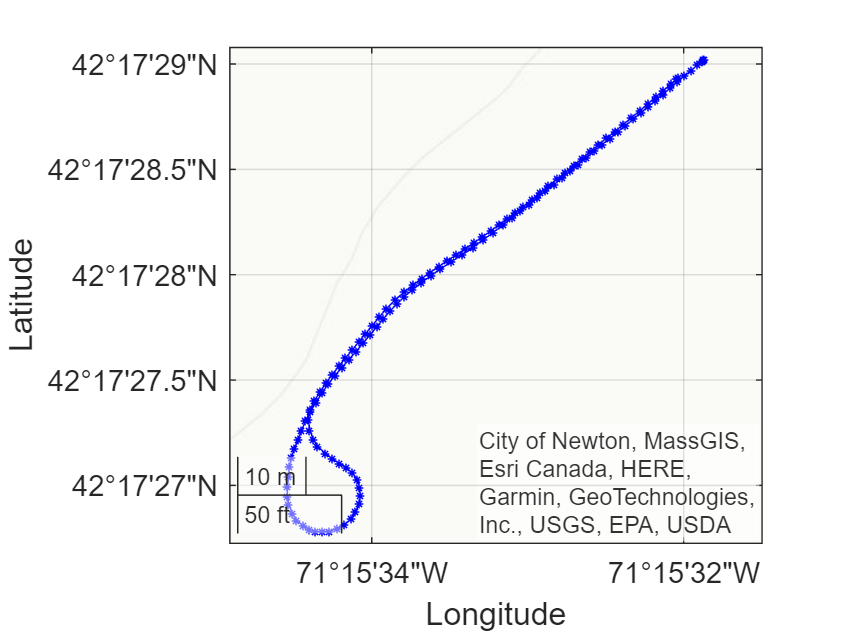

%%% SETUP GPS MAP

% Load Data
[lat1,lon1,UTCDateTime1]=PlotGPSlog( ...
    "RTK_GPS\GPS_Right_Forest_True.ubx");

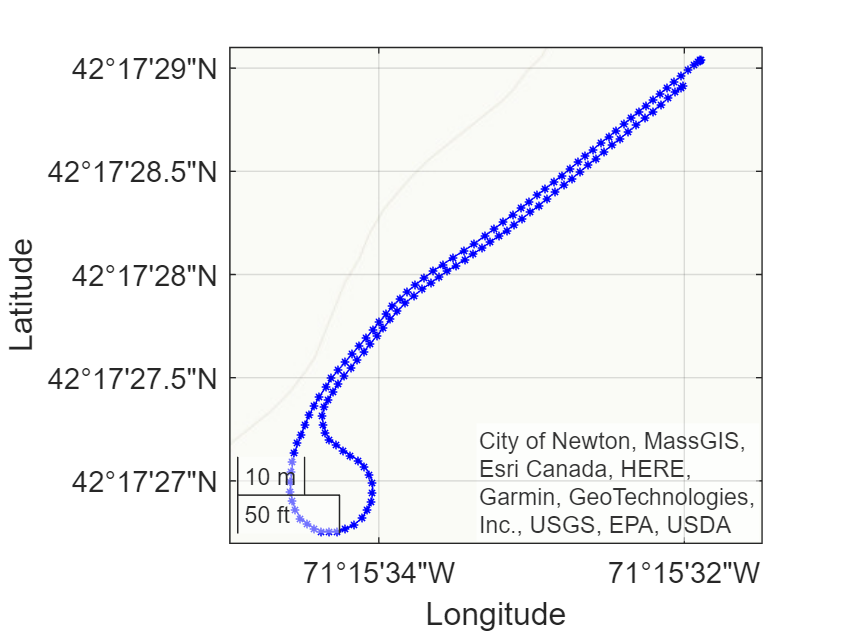

[lat2,lon2,UTCDateTime2]=PlotGPSlog( ...
    "RTK_GPS\GPS_Left_Forest_True.ubx");


% Check Starts of Data
if  UTCDateTime1(1,1)< UTCDateTime2(1,1)
    for i=1:size(lat1,2)
        if  UTCDateTime1(1,i)==UTCDateTime2(1,1)
            start=i
            disp("Found1")
        break
        end
    end
    sizearray=size(lat2,2);
    lat1new=lat1(1,start:start+sizearray-1);
    lon1new=lon1(1,start:start+sizearray-1);
    lat2new=lat2(1,1:size(lat1new,2));
    lon2new=lon2(1,1:size(lat1new,2));

else
    for i=1:size(lat2,2)
        if  UTCDateTime1(1,1)==UTCDateTime2(1,i)
        start=i
    disp("Found2")
    break
    end
    end

    % Check ends of Data
    if UTCDateTime1(1,end)< UTCDateTime2(1,end)
        sizearray=size(lat1,2)
        lat2new=lat2(1,start:start+sizearray-1);
        lon2new=lon2(1,start:start+sizearray-1);
        lat1new=lat1(1,1:size(lat2new,2));
        lon1new=lon1(1,1:size(lat2new,2));
    else
         lat2new=lat2(1,start:end);
         lon2new=lon2(1,start:end);
         length=size(lon2new,2);
        lat1new=lat1(1,1:length);
        lon1new=lon1(1,1:length);
    end
end

start = 34

Found2


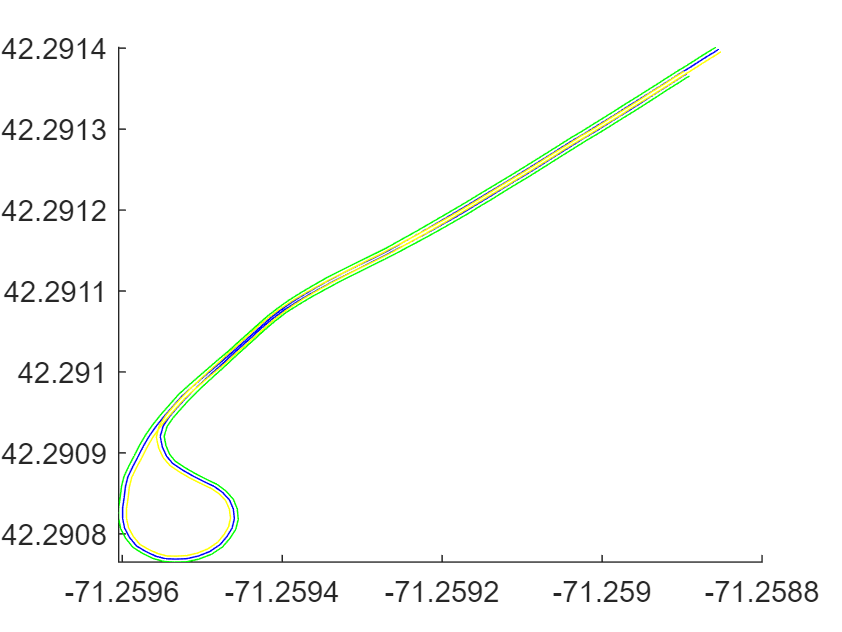


% Generate Middle Line
clf
middlelat=mean([lat1new; lat2new]);
middlelon=mean([lon1new; lon2new]);
waypoints=[middlelat(5:2:end);middlelon(5:2:end)];
figure(2)
start=1;
section=size(middlelat,2);
hold on
plot(middlelon(start:section),middlelat(start:section),'-b');
plot(lon1new(start:section),lat1new(start:section),'-y');
plot(lon2new(start:section),lat2new(start:section),'-g');
hold off


% Clean Workspace
vars = {'i','lat1','lat1new','lat2','lat2new','length','lon1','lon1new','lon2','lon2new',...
    'middlelat','middlelon','section','start','UTCDateTime1','UTCDateTime2'}

vars = 1×16 cell array
    {'i'}    {'lat1'}    {'lat1new'}    {'lat2'}    {'lat2new'}    {'length'}    {'lon1'}    {'lon1new'}    {'lon2'}    {'lon2new'}    {'middlelat'}    {'middlelon'}    {'section'}    {'start'}    {'UTCDateTime1'}    {'UTCDateTime2'}


clear (vars{:});
clear vars;

objects1 = setupGPSDemo('COM7')

Warning! RoboClaw must be OFF before runnin this code
Lights ON = CONNECTED
Please Power up RoboClaw Now
MEGA CONNNECTED
SUCCESS: Sent termination signal to the process "cmd.exe" with PID 4744. 
SUCCESS: Sent termination signal to the process "cmd.exe" with PID 10844. 
SUCCESS: Sent termination signal to the process "cmd.exe" with PID 10032. 
^C

ans = -1.0737e+09

Configure GPS RTK
1. Close Command lines
2. Open U Center
3. Connect to GPS sensor with 9600 Buad (Check Device Manager for COM #)
4. Setup RTK, go to NTRIP Client Settings
5. Credientals 1:IP address: 66.128.64.251Port: 31000Username: cbabePassword: deere1#
6. Credientals 2
7. Click Mount Point details and select RTCM3_MAMI (MAMI is the closest RTK Station)
8. Click ok
9. RTK data should be sending to the GPS (On the GPS-RTK-SMA ZED-F9P the Green RTK light should blink and eventually turn off after the GPS gets an RTK fix)
10. Create a new document named: C:\Users\Skull\Documents\GatorTemp\RTK_GPS\GPS_1_Data.ubx
11. Create a new document named: C:\Users\Skull\Documents\GatorTemp\RTK_GPS\GPS_2_Data.ubx
More information is avalible at: https://macors.massdot.state.ma.us/SBC/Account/Index?returnUrl=%2FSBC
Username: cbabe
Password: deere850
Press any key to continue
GPS CONNNECTED


objects1 = struct with fields:
    Mega: [1×1 struct]


%%% MAIN

% Variable Setup
wayStep=1

wayStep =      1


controlFlag = 1;  

% Init voltage control
senseobjects=sense(objects1);
[motorControls, wayStep]=thinkPathB2C(senseobjects, waypoints, wayStep);

steer =   -2.804591322601226



motorControls.throttle=0;
motorControls.steer=0;
oldmotorControls  = struct( ...
    "throttle", [],...
    "steer",[]);
actGPS(objects1.Mega, motorControls,oldmotorControls)

steerAng =    0.500000000000000


oldmotorControls=motorControls

oldmotorControls = struct with fields:
    throttle: 0
       steer: 0



disp("Turn on Linear Actuators") 

Turn on Linear Actuators


pause

% Main Loop
while (controlFlag > 0)           % loop for number of elements in t

    % Sense
    senseobjects = sense(objects1)

    % Think
    [motorControls, wayStep]=thinkPathB2C(senseobjects, waypoints, wayStep);
    motorControls

    % Act
    actGPS(objects1.Mega, motorControls,oldmotorControls);

    % Post-loop cleanup
    controlFlag = controlFlag+1;         % increment loops

    % End-of-path checker
    if wayStep>size(waypoints,2)
        disp("END")
        motorControls.throttle=-1;
        actGPS(objects1.Mega, motorControls,oldmotorControls)
        break 
    end

    % Update MotorControls
    oldmotorControls=motorControls; 
    
    % Current Waypoint
    wayStep
end 

senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   -3.567771033308986


motorControls = struct with fields:
    throttle: 1
       steer: 0


steerAng =    0.500000000000000


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   -3.567771033308986


motorControls = struct with fields:
    throttle: 1
       steer: 0


steerAng =    0.500000000000000


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   -3.567771033308986


motorControls = struct with fields:
    throttle: 1
       steer: 0


steerAng =    0.500000000000000


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   -2.930268349992161


motorControls = struct with fields:
    throttle: 1
       steer: 0


steerAng =    0.500000000000000


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   -2.930268349992161


motorControls = struct with fields:
    throttle: 1
       steer: 0


steerAng =    0.500000000000000


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   -2.930268349992161


motorControls = struct with fields:
    throttle: 1
       steer: 0


steerAng =    0.500000000000000


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   -2.930268349992161


motorControls = struct with fields:
    throttle: 1
       steer: 0


steerAng =    0.500000000000000


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   17.459204818732729


motorControls = struct with fields:
    throttle: 1
       steer: 17.459204818732729


steerAng =    0.395244771087604


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   17.459204818732729


motorControls = struct with fields:
    throttle: 1
       steer: 17.459204818732729


steerAng =    0.395244771087604


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -38.425191010232311


motorControls = struct with fields:
    throttle: 1
       steer: -38.425191010232311


steerAng =    0.730551146061394


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   28.750833816175344


motorControls = struct with fields:
    throttle: 1
       steer: 28.750833816175344


steerAng =    0.327494997102948


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   28.750833816175344


motorControls = struct with fields:
    throttle: 1
       steer: 28.750833816175344


steerAng =    0.327494997102948


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -45.289020451288877


motorControls = struct with fields:
    throttle: 1
       steer: -45.289020451288877


steerAng =    0.771734122707733


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -45.289020451288877


motorControls = struct with fields:
    throttle: 1
       steer: -45.289020451288877


steerAng =    0.771734122707733


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -45.289020451288877


motorControls = struct with fields:
    throttle: 1
       steer: -45.289020451288877


steerAng =    0.771734122707733


wayStep =      1


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   39.306589641888365


motorControls = struct with fields:
    throttle: 1
       steer: 39.306589641888365


steerAng =    0.264160462148670


wayStep =      2


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =     -1.822740117716807e+02


motorControls = struct with fields:
    throttle: 1
       steer: -50


steerAng =    0.800000000000000


wayStep =      3


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =     -1.822740117716807e+02


motorControls = struct with fields:
    throttle: 1
       steer: -50


steerAng =    0.800000000000000


wayStep =      4


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =     -1.279120553549569e+02


motorControls = struct with fields:
    throttle: 1
       steer: -50


steerAng =    0.800000000000000


wayStep =      5


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =     -2.120570613650958e+02


motorControls = struct with fields:
    throttle: 1
       steer: -50


steerAng =    0.800000000000000


wayStep =      6


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =     -2.084983997839266e+02


motorControls = struct with fields:
    throttle: 1
       steer: -50


steerAng =    0.800000000000000


wayStep =      7


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -64.464799856986559


motorControls = struct with fields:
    throttle: 1
       steer: -50


steerAng =    0.800000000000000


wayStep =      8


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   42.007161102489022


motorControls = struct with fields:
    throttle: 1
       steer: 42.007161102489022


steerAng =    0.247957033385066


wayStep =      8


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   42.007161102489022


motorControls = struct with fields:
    throttle: 1
       steer: 42.007161102489022


steerAng =    0.247957033385066


wayStep =      8


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -61.512209011626084


motorControls = struct with fields:
    throttle: 1
       steer: -50


steerAng =    0.800000000000000


wayStep =      8


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   -9.387184845054776


motorControls = struct with fields:
    throttle: 1
       steer: -9.387184845054776


steerAng =    0.556323109070329


wayStep =      9


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   16.359999634449679


motorControls = struct with fields:
    throttle: 1
       steer: 16.359999634449679


steerAng =    0.401840002193302


wayStep =      9


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -59.402794974977411


motorControls = struct with fields:
    throttle: 1
       steer: -50


steerAng =    0.800000000000000


wayStep =      9


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -59.402794974977411


motorControls = struct with fields:
    throttle: 1
       steer: -50


steerAng =    0.800000000000000


wayStep =      9


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -59.402794974977411


motorControls = struct with fields:
    throttle: 1
       steer: -50


steerAng =    0.800000000000000


wayStep =      9


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   26.024051656431396


motorControls = struct with fields:
    throttle: 1
       steer: 26.024051656431396


steerAng =    0.343855690061412


wayStep =      9


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -88.282552383610664


motorControls = struct with fields:
    throttle: 1
       steer: -50


steerAng =    0.800000000000000


wayStep =      9


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -88.282552383610664


motorControls = struct with fields:
    throttle: 1
       steer: -50


steerAng =    0.800000000000000


wayStep =      9


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -39.112194637114698


motorControls = struct with fields:
    throttle: 1
       steer: -39.112194637114698


steerAng =    0.734673167822688


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =    8.757784631219920


motorControls = struct with fields:
    throttle: 1
       steer: 8.757784631219920


steerAng =    0.447453292212680


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -47.112402073094245


motorControls = struct with fields:
    throttle: 1
       steer: -47.112402073094245


steerAng =    0.782674412438566


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -47.112402073094245


motorControls = struct with fields:
    throttle: 1
       steer: -47.112402073094245


steerAng =    0.782674412438566


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -36.218385254951556


motorControls = struct with fields:
    throttle: 1
       steer: -36.218385254951556


steerAng =    0.717310311529709


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -36.218385254951556


motorControls = struct with fields:
    throttle: 1
       steer: -36.218385254951556


steerAng =    0.717310311529709


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -35.272829619874017


motorControls = struct with fields:
    throttle: 1
       steer: -35.272829619874017


steerAng =    0.711636977719244


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -35.272829619874017


motorControls = struct with fields:
    throttle: 1
       steer: -35.272829619874017


steerAng =    0.711636977719244


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -35.272829619874017


motorControls = struct with fields:
    throttle: 1
       steer: -35.272829619874017


steerAng =    0.711636977719244


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -36.218385254951556


motorControls = struct with fields:
    throttle: 1
       steer: -36.218385254951556


steerAng =    0.717310311529709


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -36.218385254951556


motorControls = struct with fields:
    throttle: 1
       steer: -36.218385254951556


steerAng =    0.717310311529709


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -36.218385254951556


motorControls = struct with fields:
    throttle: 1
       steer: -36.218385254951556


steerAng =    0.717310311529709


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =  -52.669652580388203


motorControls = struct with fields:
    throttle: 1
       steer: -50


steerAng =    0.800000000000000


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   -0.191022040780553


motorControls = struct with fields:
    throttle: 1
       steer: 0


steerAng =    0.500000000000000


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   -0.191022040780553


motorControls = struct with fields:
    throttle: 1
       steer: 0


steerAng =    0.500000000000000


wayStep =     10


senseobjects = struct with fields:
    gpsData: [1×1 struct]


steer =   -0.191022040780553


motorControls = struct with fields:
    throttle: 1
       steer: 0


steerAng =    0.500000000000000


wayStep

%%% SHUTDOWN
clear